# TurbOPark examples

Author: Sidse Damgaard Hansen, Nicolai Gayle Nygaard

Checked by: Cecilia Mortensen Kobæk

Copyright (c) 2022 by Ørsted

# Example 1

Simple square wind farm with identical turbines.

## Define wind farm

4x4 wind farm with 6 rotor diameter distance (rotor diameter beeing 120 m)

[X,Y] = meshgrid((0:3)*120*6, (0:3)*120*6);

Plot the layout

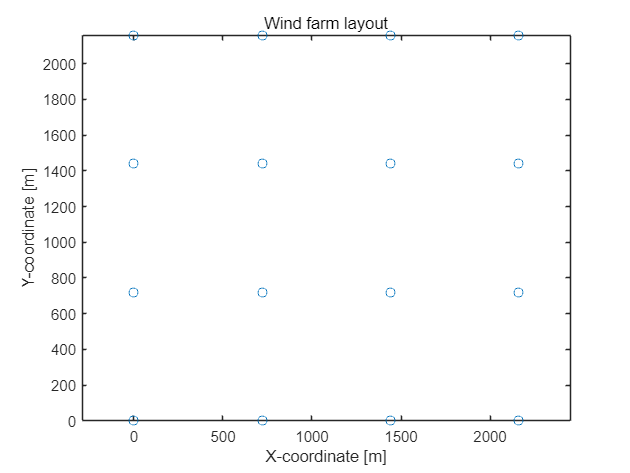

figure; plot(X(:),Y(:),'o')
axis equal
title('Wind farm layout'); xlabel('X-coordinate [m]'); ylabel('Y-coordinate [m]')

### Define the power curve struct

Wind speed bins that the power curve is defined at

v = 0:0.5:25.5; 

And the corresponding power and thrust values

pow = [0	0	0	0	5	15	37	73	122	183	259	357	477	622	791	988	1212	1469	1755	2009	2176	2298,...
   	2388	2447	2485	2500	2500	2500	2500	2500	2500	2500	2500	2500	2500	2500	2500	2500	2500,...
   	2500	2500	2500	2500	2500	2500	2500	2500	2500	2500	2500	2500	0];
ct  = [0	0	0	0	0.78	0.77	0.78	0.78	0.77	0.77	0.78	0.78	0.78	0.78	0.78	0.78	0.77	0.77,...
   	0.77	0.76	0.73	0.7	0.68	0.52	0.42	0.36	0.31	0.27	0.24	0.22	0.19	0.18	0.16	0.14	0.13,...
   	0.12	0.11	0.1	0.09	0.08	0.08	0.08	0.07	0.07	0.06	0.06	0.06	0.05	0.05	0.05	0.04	0];

Plot the power and Ct curves

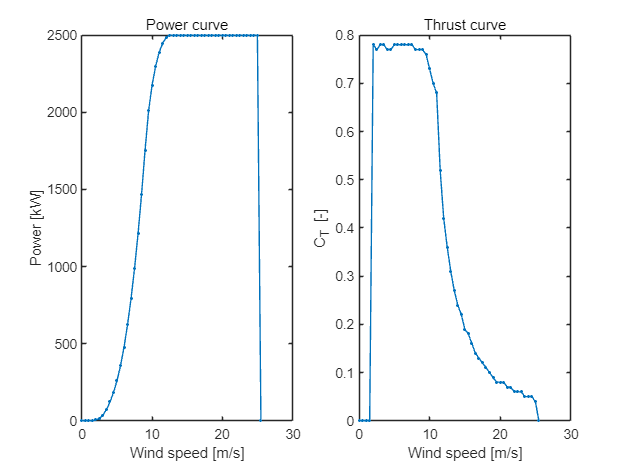

figure
subplot(1,2,1)
plot(v, pow, '.-')
title('Power curve'); xlabel('Wind speed [m/s]'); ylabel('Power [kW]')
subplot(1,2,2)
plot(v, ct, '.-')
title('Thrust curve'); xlabel('Wind speed [m/s]'); ylabel('C_T [-]')

Make power and ct interpolants, and collect in the struct `pc` together with the rotor diameter

pc.interpolant_power = griddedInterpolant(v, pow, 'linear','nearest'); 
pc.interpolant_ct = griddedInterpolant(v, ct, 'linear','nearest');
pc.rotor_diameter = 120; 

### Define the hub height

100 m aMSL, same for all 16 turbines

hub_height = 100*ones(1,16); 

## Define inflow wind speed and direction

The freestream wind speed at a given location $\left(x_0 ,y_0 \right)$, at a given hight $z_0$ (for this example 90 m aMSL). More than one wind speed can be processed in parallel.

u0 = [6,10,14]; 
nu0 = length(u0);
z0 = 90;

Wind direction (the wake model can only run for one wind direction at the time)

direction = 270; 

Furthermore, you can define a correction to your free wind speed at $\left(x_0 ,y_0 ,z_0 \right)$ to the specific turbine location and hub height. The correction could stem from a difference between $z_0$ and the hub height of the turbine, a gradient in the wind speed across the site or the inclusion of blockage - or all of them combined.

In this example we won't include blockage or horizontal gradients (thus $\left(x_0 ,y_0 \right)$ are not needed), but we will assume a power law shear profile with a shear coefficient $\alpha$ of 0.1.

ws_corr = (hub_height/z0).^0.1; 

Ambient turbulence intensity values corresponding to the free wind speed values above: 6 m/s will have a TI value of 9%, 10 m/s of 10% etc.

ti0 = [0.09 0.1 0.11];  

## Run the TurbOPark model

[pow_waked, ws_waked] = TurbOPark(u0,direction,ws_corr,X(:),Y(:),...
    hub_height,pc,ones(1,16),ti0); 

Output `pow_waked` and `ws_waked` to enable comparison:

format longG
disp(pow_waked)

          495.429647093727          2201.84387293603                      2500
          495.429647093727          2201.84387293603                      2500
          495.429647093727          2201.84387293603                      2500
          495.429647093727          2201.84387293603                      2500
          165.681333834342          938.265716039082                      2500
          165.681333834342          938.265716039082                      2500
          165.681333834342          938.265716039082                      2500
          165.681333834342          938.265716039082                      2500
          105.264701735512          607.531414199904          2485.83000221364
          105.264701735512          607.531414199904          2485.83000221364
          105.264701735512          607.531414199904          2485.83000221364
          105.264701735512          607.531414199904          2485.83000221364
          71.8241034924664          446.254939675813

disp(ws_waked)

          6.06355050721975          10.1059175120329          14.1482845168461
          6.06355050721975          10.1059175120329          14.1482845168461
          6.06355050721975          10.1059175120329          14.1482845168461
          6.06355050721975          10.1059175120329          14.1482845168461
          4.35804371995363          7.37377085289107          12.8635577397301
          4.35804371995363          7.37377085289107          12.8635577397301
          4.35804371995363          7.37377085289107          12.8635577397301
          4.35804371995363          7.37377085289107          12.8635577397301
          3.82923165036237          6.45010832482725          12.0276667404546
          3.82923165036237          6.45010832482725          12.0276667404546
          3.82923165036237          6.45010832482725          12.0276667404546
          3.82923165036237          6.45010832482725          12.0276667404546
          3.48366810406203          5.87189558198255

Note that since the hub height is higher than the wind speed reference height `z0` the output wind speed is larger than the free stream wind speed for the front row turbines.

### Plot results

For all free wind speeds, plot the reduction of wind speed calculated by the TurbOPark model in percent

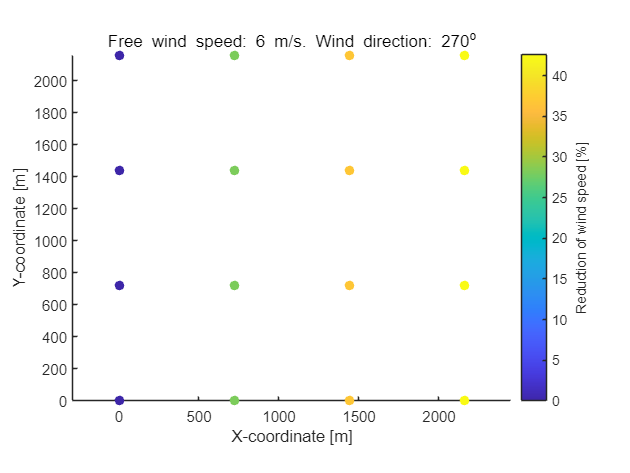

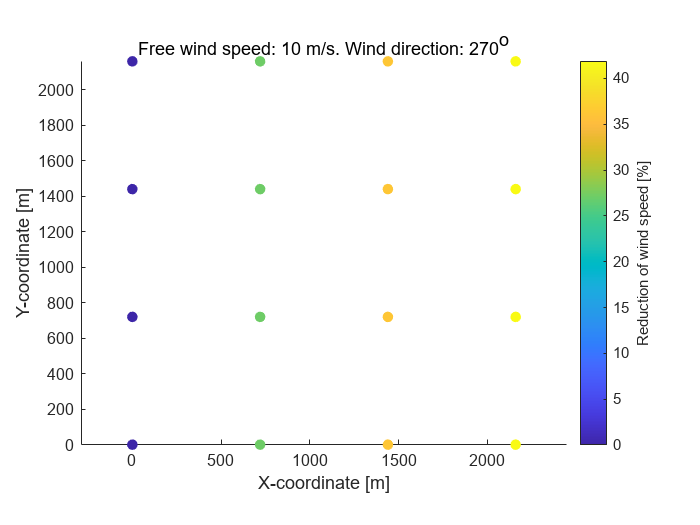

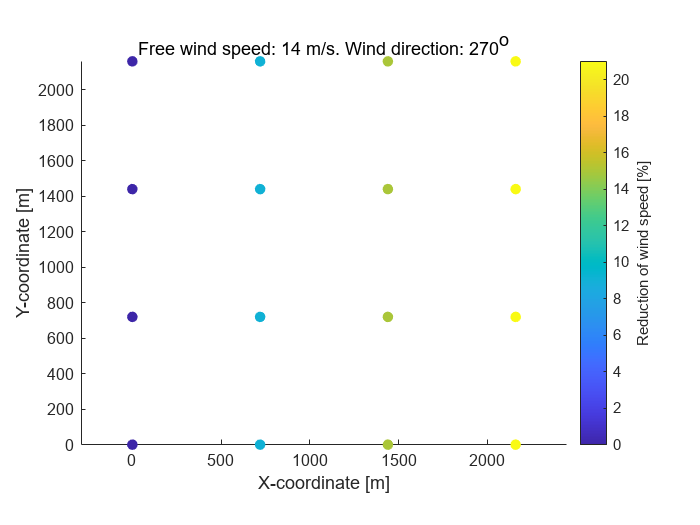

for i = 1:length(u0)
    figure; scatter(X(:), Y(:), 40, (1-ws_waked(:,i)./(u0(i)*ws_corr'))*100, 'filled')
    axis equal
    cb = colorbar; cb.Label.String = 'Reduction of wind speed [%]';
    title(['Free wind speed: ', num2str(u0(i)) ,' m/s. Wind direction: ' num2str(direction) '^o']); xlabel('X-coordinate [m]'); ylabel('Y-coordinate [m]')    
end

Wake loss for the wind farm at each inflow wind speed (ignoring blockage so the front row represents the gross power)

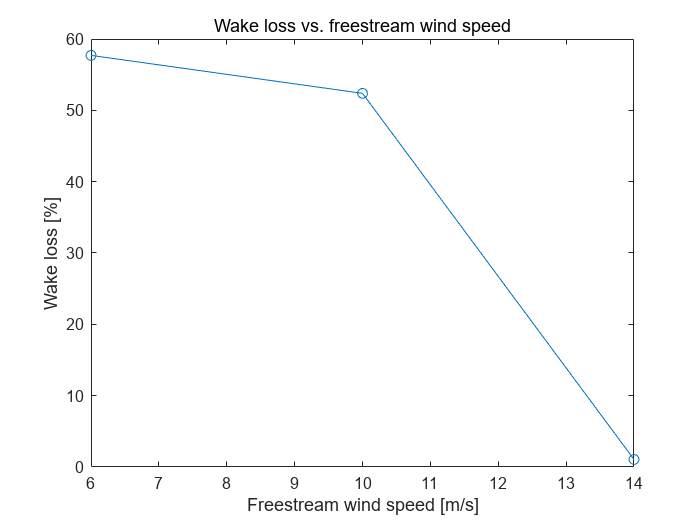

figure
nwtg = numel(X);
plot(u0, 100*(1-sum(pow_waked,1)./max(pow_waked)./nwtg), 'o-')
title('Wake loss vs. freestream wind speed'); xlabel('Freestream wind speed [m/s]'); ylabel('Wake loss [%]')

# Example 2

Same wind farm as in example 1 but with two different turbine types (most northern turbines of type 1 and most southern of type 2), and with a wind speed gradient included.

### Define and distribute the two turbine types

pc1 = pc;

v2 = 0:26;
pow2 = [0	0	0	0	54	144	289	474	730	1050	1417	1780	2041	2199	2260	2292	2299	2300	2300,...
   	2300	2300	2300	2300	2300	2300	2300	0];
ct2  = [0	0	0	0	0.94	0.82	0.76	0.68	0.86	0.83	0.77	0.68	0.66	0.52	0.47	0.41	0.38	0.34,...
   	0.27	0.26	0.23	0.22	0.22	0.2	0.16	0.17	0];

pc2.interpolant_power = griddedInterpolant(v2, pow2, 'linear','nearest'); 
pc2.interpolant_ct = griddedInterpolant(v2, ct2, 'linear','nearest');
pc2.rotor_diameter = 80; 

Plot comparing the two power curves

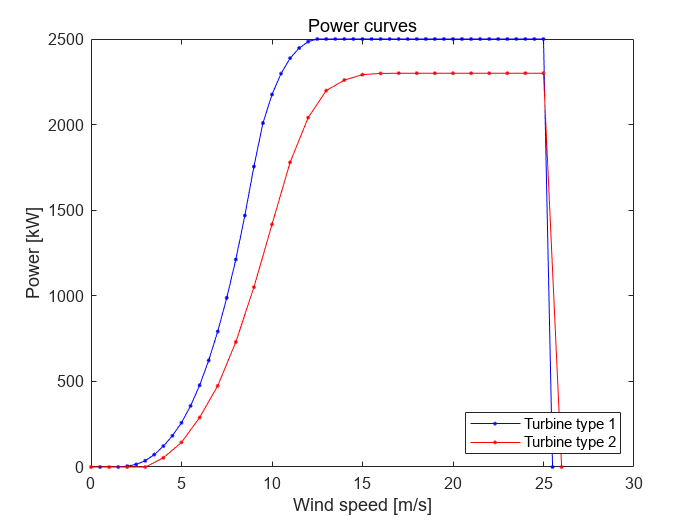

figure
plot(v, pow, 'b.-')
hold on
plot(v2, pow2, 'r.-')
legend('Turbine type 1', 'Turbine type 2','Location','SouthEast')
title('Power curves'); xlabel('Wind speed [m/s]'); ylabel('Power [kW]')

Distribute the two turbine types to the turbine positions using `power_curve_index`

power_curve_index = 1 + 1.0*(Y(:)<=720)'

power_curve_index =      2     2     1     1     2     2     1     1     2     2     1     1     2     2     1     1


Illustration of turbine type by location

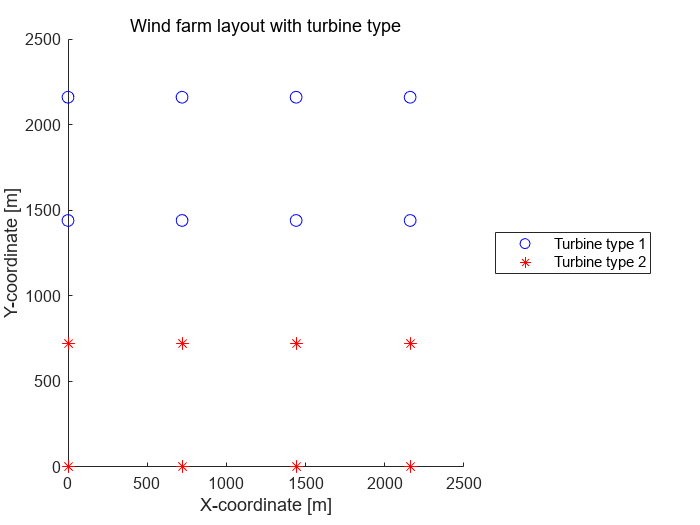

figure
idx1 = power_curve_index == 1;
idx2 = power_curve_index == 2;
scatter(X(idx1), Y(idx1), 50, 'bo')
hold on
scatter(X(idx2), Y(idx2), 50, 'r*')
legend('Turbine type 1', 'Turbine type 2','Location','EastOutSide')
title('Wind farm layout with turbine type'); xlabel('X-coordinate [m]'); ylabel('Y-coordinate [m]')

Hub height of turbine type 2 is set to 70 m aMSL

hub_height(power_curve_index == 2) = 70;

### Define a horizontal correction

In this example we will include a "random" wind speed gradient across the site with lower wind speeds in south-west and higher in north-east. We will in this example place the free wind speed reference point $\left(x_0 ,y_0 \right)$ at the same position as the first turbine*.* The reference position where the freestream wind speed is defined is still at a height of 90 m aMSL.

x_pt = -100:100:3000; y_pt = x_pt;
[X_pt,Y_pt] = ndgrid(x_pt,y_pt);
grad = ((X_pt-5).^2 + (Y_pt).^2)*10^-8 + 1;
grad_int = griddedInterpolant(X_pt,Y_pt,grad);

Plot the wind farm layout on top of the wind speed gradient

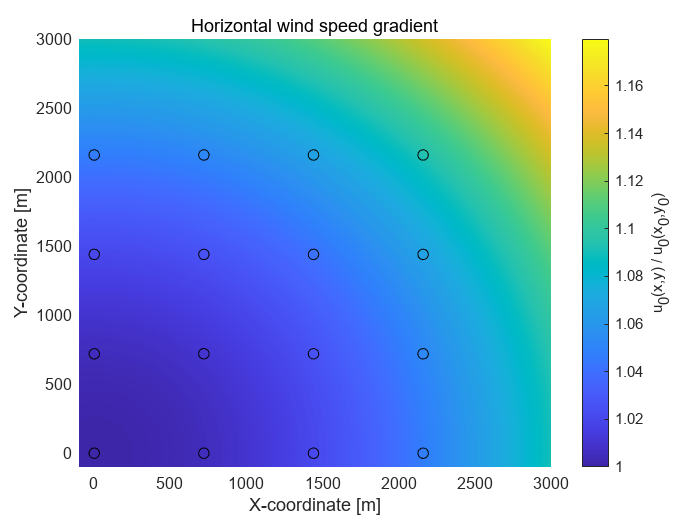

figure; pcolor(x_pt, y_pt, grad_int(X_pt,Y_pt)./grad_int(X(1),Y(1))); shading interp; c = colorbar;
c.Label.String = 'u_0(x,y) / u_0(x_0,y_0)';
hold on
scatter(X(:),Y(:),40,'ko')
title('Horizontal wind speed gradient'); xlabel('X-coordinate [m]'); ylabel('Y-coordinate [m]')

Now combine the effect of the wind speed gradient and shear in the correction of the free wind speed `ws_corr `(remember we defined the free wind speed position $\left(x_0 ,y_0 \right)$ to be `(X(1),Y(1))`)

ws_corr = (hub_height/z0).^0.1; % Effect of shear
ws_corr = ws_corr .* grad_int(X(:),Y(:))'./grad_int(X(1),Y(1)); % Add effect of horizontal gradient

## Run the TurbOPark model

[pow_waked, ws_waked] = TurbOPark(u0,direction,ws_corr,X(:),Y(:),...
    hub_height,[pc1, pc2],power_curve_index,ti0); 

Output `pow_waked` and `ws_waked` to enable comparison:

disp(pow_waked)

          267.408098975358          1325.91692326387            2238.805191408
            271.8198199871          1344.52728661225          2243.13577732067
          531.934637441146          2253.03477894046                      2500
          577.513122499193          2311.97909224055                      2500
          87.8716269861529          549.915174301573          1860.30802639162
           90.029536518109          560.285573640592          1879.96345820567
          179.445496763605          1030.67640805119                      2500
          195.741429267846          1133.76926324207                      2500
          56.3363587519906          421.529493247156          1453.25377990821
          57.8305559469565          426.318770082901          1476.12985730185
          120.791650152783          701.169901423848                      2500
          132.472056081865          765.870852417475                      2500
          50.9865832982385          379.447075562596

disp(ws_waked)

          5.85109033776109          9.75181722960182          13.6525441214426
          5.88151599991104          9.80252666651839          13.7235373331257
          6.18942978427981           10.315716307133          14.4420028299862
          6.34659697413515          10.5776616235586           14.808726272982
          4.37635141095725          7.29654364961552          11.3076935877073
          4.40032818353454          7.33705302203356          11.3830017555773
          4.47086472757053          7.59525983939998          13.2633760517144
          4.58382519255162          7.82537781973676          13.7197242744724
          4.02595954168878          6.71637563917382          10.0998726719234
          4.04256173274396          6.74226362206974          10.1628921688756
           3.9876698995182          6.73423047758535          12.7262841310504
          4.08583652526119          6.92565340951916          13.2610220831519
          3.94419598700442          6.48890311114917

Note that since the hub height of the northern turbines is higher than the wind speed reference height `z0`, the output wind speed at the northern front row turbines is larger than the free stream wind speed (also helped by the horizontal wind speed gradient). Conversely, the hub height of the southern turbines is lower than `z0` and the output wind speed of these front row turbines is less than the free stream wind speed.

### Plot results

For all free wind speeds, plot the reduction of wind speed calculated by the TurbOPark model in percent

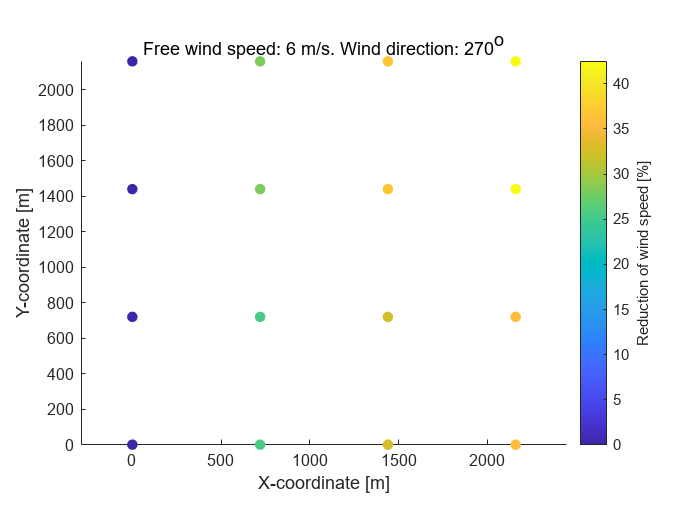

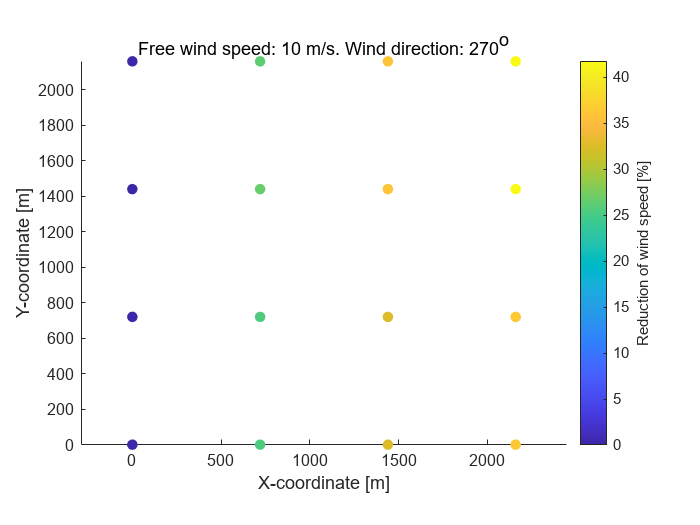

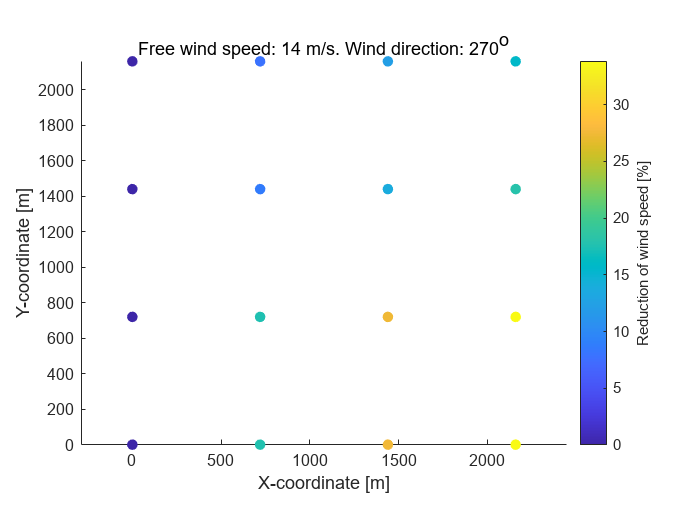

for i = 1:length(u0)
    figure; scatter(X(:), Y(:), 40, (1-ws_waked(:,i)./(u0(i)*ws_corr'))*100, 'filled')
    axis equal
    cb = colorbar; cb.Label.String = 'Reduction of wind speed [%]';
    title(['Free wind speed: ', num2str(u0(i)) ,' m/s. Wind direction: ' num2str(direction) '^o']); xlabel('X-coordinate [m]'); ylabel('Y-coordinate [m]')    
end

Plot of the power along different turbine rows (labelled 1-4 from south to north)

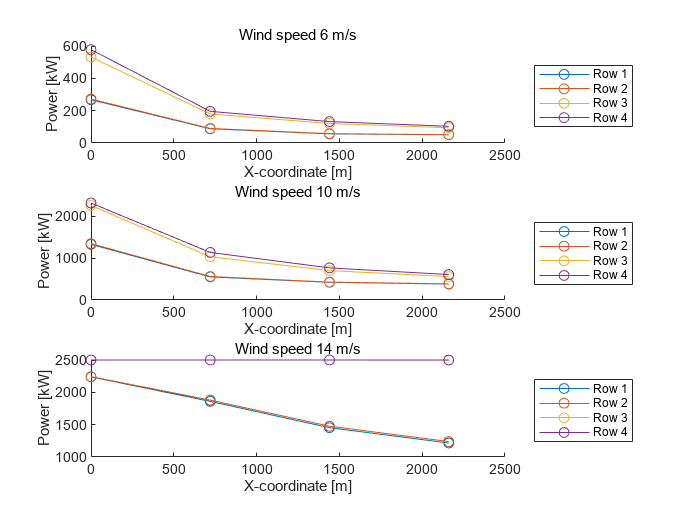

figure
ys = unique(Y);
% Turbine row numbers 1-4
iRow1 = Y == ys(1);
iRow2 = Y == ys(2);
iRow3 = Y == ys(3);
iRow4 = Y == ys(4);
for i=1:nu0
    subplot(nu0,1,i)
    hold on
    plot(X(iRow1), pow_waked(iRow1,i),'o-'); title(['Wind speed ',num2str(u0(i)),' m/s']); xlabel('X-coordinate [m]'); ylabel('Power [kW]')
    plot(X(iRow2), pow_waked(iRow2,i),'o-'); title(['Wind speed ',num2str(u0(i)),' m/s']); xlabel('X-coordinate [m]'); ylabel('Power [kW]')
    plot(X(iRow3), pow_waked(iRow3,i),'o-'); title(['Wind speed ',num2str(u0(i)),' m/s']); xlabel('X-coordinate [m]'); ylabel('Power [kW]')
    plot(X(iRow4), pow_waked(iRow4,i),'o-'); title(['Wind speed ',num2str(u0(i)),' m/s']); xlabel('X-coordinate [m]'); ylabel('Power [kW]')
    legend('Row 1','Row 2','Row 3','Row 4','Location','EastOutSide')
end